# Hypothesis Testing

## Why do we need it for an AI project?

Helps answer:

- Is the model better than random?

- Is the difference between variables significant? Is it real?

- Is the correlation strong enough?

- Are two datasets (e.g. training and test) similar?

- Is the training data representative of the whole population?

## Null hypothesis and p-values

- **Null hypothesis:** there is no difference between two (or more) variables or groups

- ***p*****-value:** the probability that the null hypothesis is true

## Comparing variables in the Framingham dataset

Begin by loading the Framingham dataset.

fram = readtable("../frmgham.xls");

Create a boxplot to compare BMI betwen males and females.

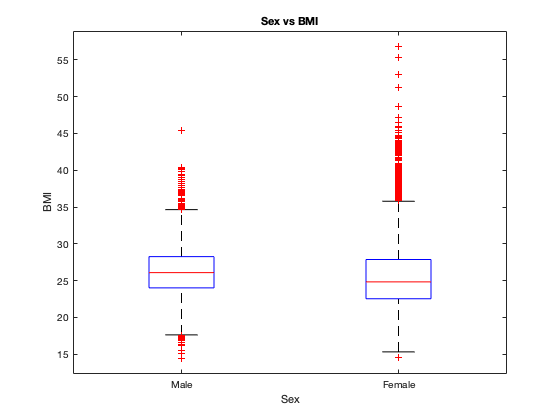

boxplot(fram.BMI, fram.SEX, "Labels", {'Male','Female'})
xlabel("Sex")
ylabel("BMI")
title("Sex vs BMI")

Is the difference in BMI between males and females significant statistically?

We can check the significance using a **t-test**. In MATLAB, this is done with the `ttest2` function. The t-test checks if the two distributions (in this case BMI of males and females) have equal means. 

The first output, *h*, signifies whether the test rejects or fails to reject the null hypothesis. A value of 1 indicates that the null hypothesis is rejected at a significance level of 5%, and a value of 0 indicates that we fail to reject the null hypothesis. 

The second output of `ttest2 `will be the *p-*value*.*

[h, p_value] = ttest2(fram.BMI(fram.SEX==1), fram.BMI(fram.SEX==2))

h = 1

p_value = 7.4557e-14

Based on the value of *h, *we can reject the null hypothesis. What does the *p-*value say about the two distributions?

If the null hypothesis is true and there is no relationship between sex and BMI, the probability of getting results as extreme as ours is $7\ldotp 4557*{10}^{-14}$.   

## T-test assumptions

- T-test assumes that distributions are "normal".

- T-test compares the mean and not the median.

## How do we know if the data is "normal"?

Plot it! Use `histogram` to plot BMI, cholesterol and glucose for males and females.

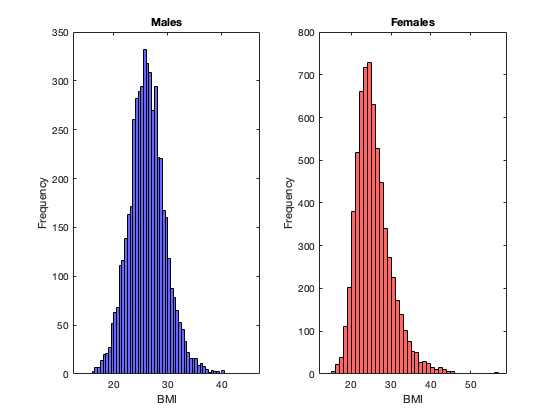

figure;
subplot(1,2,1)
histogram(fram.BMI(fram.SEX==1),"FaceColor","blue");
xlabel('BMI')
ylabel('Frequency')
title('Males')

subplot(1,2,2)
histogram(fram.BMI(fram.SEX==2),"FaceColor","red");
xlabel('BMI')
ylabel('Frequency')
title('Females')

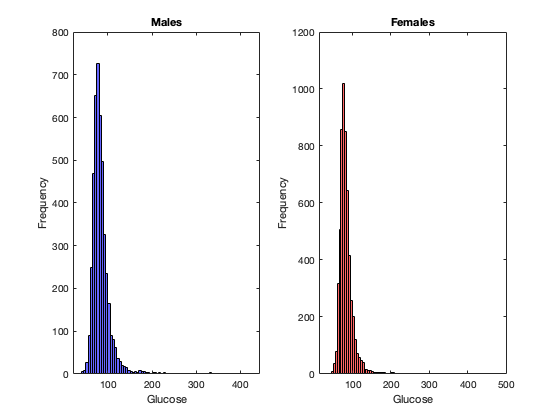

figure;
subplot(1,2,1)
histogram(fram.GLUCOSE(fram.SEX==1),"FaceColor","blue");
xlabel('Glucose')
ylabel('Frequency')
title('Males')

subplot(1,2,2)
histogram(fram.GLUCOSE(fram.SEX==2),"FaceColor","red");
xlabel('Glucose')
ylabel('Frequency')
title('Females')

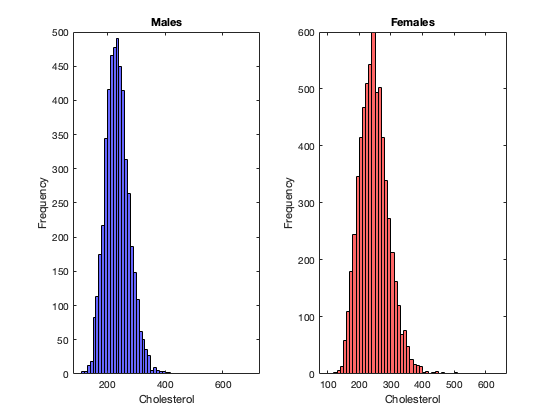

figure;
subplot(1,2,1)
histogram(fram.TOTCHOL(fram.SEX==1),"FaceColor","blue");
xlabel('Cholesterol')
ylabel('Frequency')
title('Males')

subplot(1,2,2)
histogram(fram.TOTCHOL(fram.SEX==2),"FaceColor","red");
xlabel('Cholesterol')
ylabel('Frequency')
title('Females')

Are the data normally distributed? They look to be fairly normal, but the right tails in all of the plots look a bit longer than the left tails. To get a better idea about the data normality, we can use `normplot`. This function compares the input distribution to an ideal normal distribution.


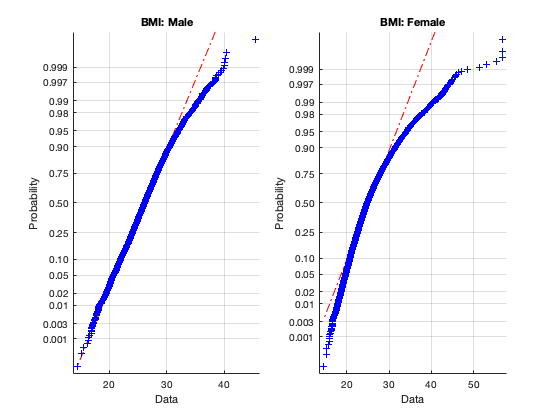

figure;
subplot(1,2,1)
normplot(fram.BMI(fram.SEX==1))
title('BMI: Male')

subplot(1,2,2)
normplot(fram.BMI(fram.SEX==2))
title('BMI: Female')

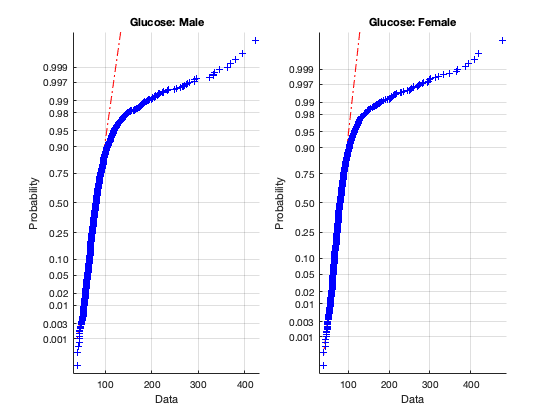

figure;
subplot(1,2,1)
normplot(fram.GLUCOSE(fram.SEX==1))
title('Glucose: Male')

subplot(1,2,2)
normplot(fram.GLUCOSE(fram.SEX==2))
title('Glucose: Female')

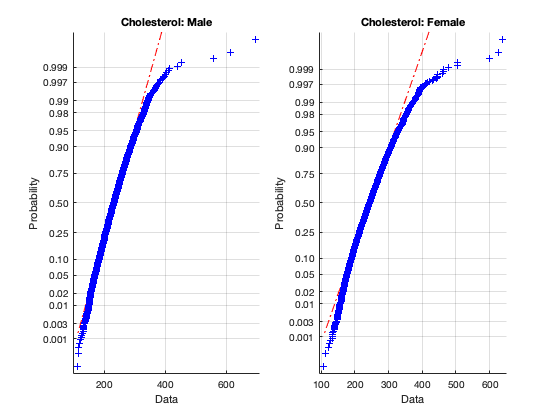

figure;
subplot(1,2,1)
normplot(fram.TOTCHOL(fram.SEX==1))
title('Cholesterol: Male')

subplot(1,2,2)
normplot(fram.TOTCHOL(fram.SEX==2))
title('Cholesterol: Female')

The normality tests confirm that the data is right-skewed in all six cases.

## Rank sum test

The **rank sum test **can be used to compare medians for any distribution (not necessarily 'normal')

Compare BMI between males and females using the `ranksum` function. Note that the outputs are in the reverse order compared to the `ttest2` function. 

[p_rank, h_rank] = ranksum(fram.BMI(fram.SEX==1), fram.BMI(fram.SEX==2))

p_rank = 1.3124e-44

h_rank = logical
   1


Are these results consistent with those from the t-test?

With the rank sum test, the null hypothesis is that the two samples are from distributions with equal medians. As with the `ttest2` function, an output of h = 1 means that the null hypothesis is rejected. 

## Interpreting *p*-values

*P-*values alone can be misleading; always use it in conjunction with a plot and other statistical metrics (e.g. fold change)

Plot the distribution between males and females for features 3 through 14 using `boxplot` and `subplot.`

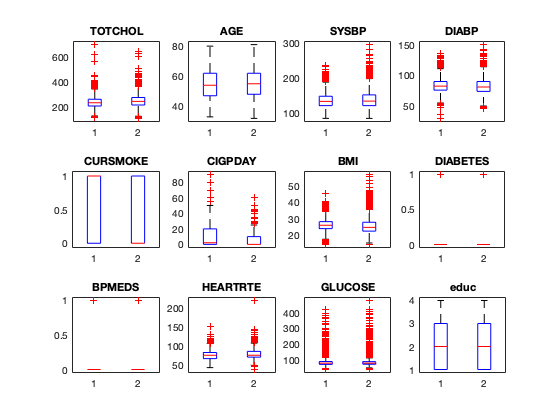

figure;
for i = 3:14
    subplot(3,4,i-2)
    boxplot(fram.(i),fram.SEX)
    title(fram.Properties.VariableNames(i))
end

By looking at the boxplots, can you guess if the *p-*values will be less than 0.05?

Calculate the *p-*values using both t-test and ranksum test.

% Create empty matrices to store h and p-values
h_ttest = zeros(1,12);
p_ttest = zeros(1,12);
p_rank = zeros(1,12);
h_rank = zeros(1,12);
j = 1;

% use for loop to perform t-test and ranksum test for each feature
for i = 3:14
    [h_ttest(j), p_ttest(j)] = ttest2(fram.(i)(fram.SEX==1), fram.(i)(fram.SEX==2));
    [p_rank(j), h_rank(j)] = ranksum(fram.(i)(fram.SEX==1), fram.(i)(fram.SEX==2));
    j = j + 1;
end

% Create table with h and p-values for two test types
t = splitvars(table([h_ttest', p_ttest', h_rank', p_rank']));
t.Properties.VariableNames = {'h_ttest', 'p_ttest', 'h_rank', 'p_rank'};
t.Properties.RowNames = fram.Properties.VariableNames(3:14)

t = 12×4 table
                h_ttest      p_ttest      h_rank      p_rank   
                _______    ___________    ______    ___________

    TOTCHOL        1        4.6059e-46      1        9.4422e-44
    AGE            1         0.0032661      1         0.0036172
    SYSBP          1        2.4594e-07      1         0.0041453
    DIABP          1        1.2661e-07      1        2.9421e-10
    CURSMOKE       1        8.1345e-58      1        3.2922e-57
    CIGPDAY        1       2.0925e-154      1       2.3213e-108
    BMI            1        7.4557e-14      1        1.3124e-44
    DIABETES       1          0.030667      1          0.030674
    BPMEDS         1        1.8089e-18      1        2.

According to both tests, only Glucose and Education do not meet the threshold *p-*value of 0.05. Therefore, we fail to reject the null hypothesis for those two variables.

Repeat the same process, this time comparing smokers and non-smokers.

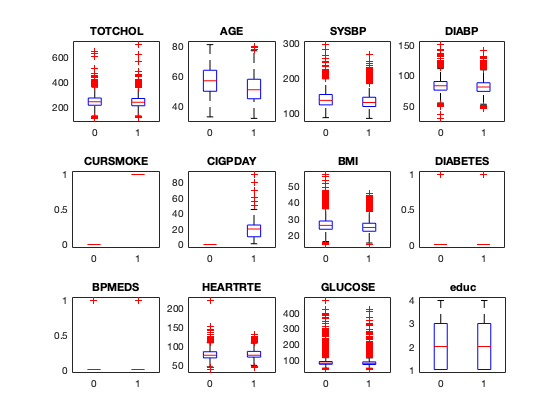

j = 1;
figure;
for i = 3:14
    % fill subplot with boxplots
    subplot(3,4,j);
    boxplot(fram.(i),fram.CURSMOKE);
    title(fram.Properties.VariableNames(i))
    
    % store h and p-values 
    [h_ttest(j), p_ttest(j)] = ttest2(fram.(i)(fram.CURSMOKE==0), ...
        fram.(i)(fram.CURSMOKE==1));
    [p_rank(j), h_rank(j)] = ranksum(fram.(i)(fram.CURSMOKE==0), ...
        fram.(i)(fram.CURSMOKE==1));

    j = j + 1;
end

t2 = splitvars(table([h_ttest', p_ttest', h_rank', p_rank']));
t2.Properties.VariableNames = {'h_ttest', 'p_ttest', 'h_rank', 'p_rank'};
t2.Properties.RowNames = fram.Properties.VariableNames(3:14)

t2 = 12×4 table
                h_ttest      p_ttest      h_rank      p_rank   
                _______    ___________    ______    ___________

    TOTCHOL        1        1.0079e-05      1        2.5056e-06
    AGE            1       8.9792e-169      1       2.0064e-163
    SYSBP          1        1.5867e-52      1        2.2563e-57
    DIABP          1        2.4474e-16      1        2.4204e-19
    CURSMOKE       1                 0      1                 0
    CIGPDAY        1                 0      1                 0
    BMI            1        1.2374e-71      1        3.2665e-74
    DIABETES       1         2.732e-06      1        2.7578e-06
    BPMEDS         1        1.2437e-19      1        1

In this case, we reject the null hypothesis for all variables except Education.

## Comparing multiple distributions using ANOVA

Compare BMI, smoking and diabetes based on education level using boxplots.

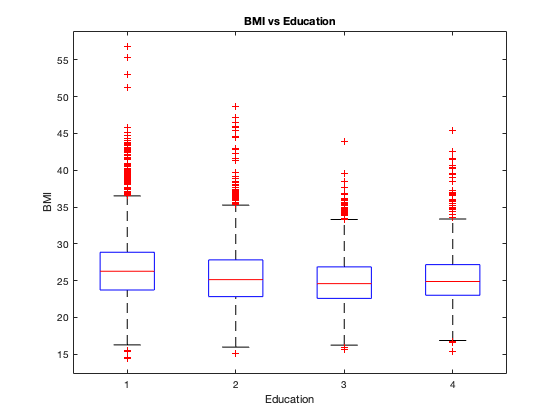

figure;
boxplot(fram.BMI, fram.educ)
title('BMI vs Education')
xlabel('Education')
ylabel('BMI')

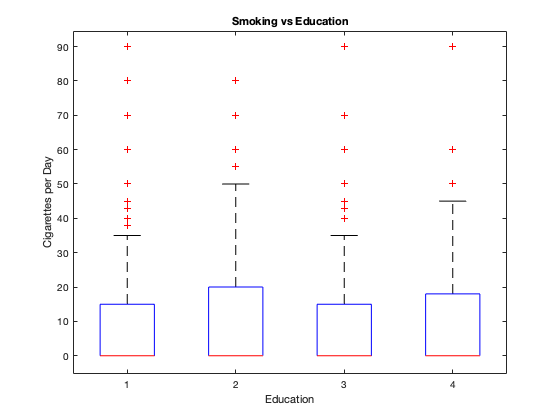

figure;
boxplot(fram.CIGPDAY, fram.educ)
title('Smoking vs Education')
xlabel('Education')
ylabel('Cigarettes per Day')

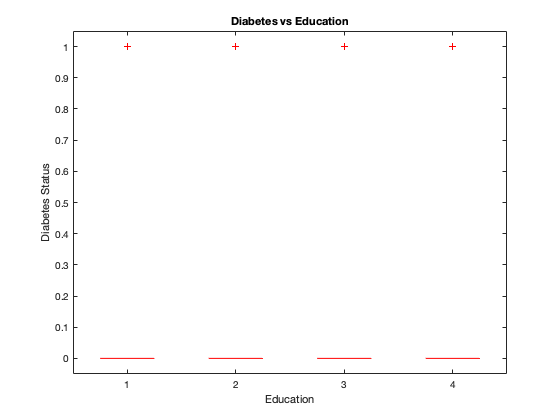

figure;
boxplot(fram.DIABETES, fram.educ)
title('Diabetes vs Education')
xlabel('Education')
ylabel('Diabetes Status')

Another useful tool for comparing groups within a dataset is the `splitapply `function. It allows you to split a dataset into groups and apply any function of your choice to each group. It helps to define the groups beforehand using the `findgroups `function. 

Find the mean for each education group within the BMI, Cigarettes per Day and Diabetes Status datasets. Because we have not removed rows with missing data, the `nanmean` function will be needed.

G = findgroups(fram.educ);
splitapply(@nanmean,fram.BMI,G)

ans =    26.6031
   25.5416
   24.9627
   25.2747


splitapply(@nanmean,fram.CIGPDAY,G)

ans =     7.7784
    9.5564
    7.0567
    8.5034


splitapply(@nanmean,fram.DIABETES,G)

ans =     0.0571
    0.0349
    0.0382
    0.0431


Are the differences between education levels significant for these three variables? We can use the ANOVA test to calculate the *p*-value.

**ANOVA **extends the t-test to multiple comparisons (also assumes the distributions are 'normal' and it compares the mean).

pvalue = anova1(fram.BMI, fram.educ,"off")      % "off" suppresses Anova table

pvalue = 1.1698e-63

pvalue = anova1(fram.CIGPDAY, fram.educ,"off")

pvalue = 6.9488e-14

pvalue = anova1(fram.DIABETES, fram.educ,"off")

pvalue = 9.9287e-06

Based on the p-values, we can infer that the means of each educational group are statistically different in regards to BMI, Cigarettes per Day and Diabetes.

The **Kruskal-Wallis test** is the equivalent of the rank-sum test for multiple comparisons. First calculate the median of each education group for BMI, Cigarettes per Day, and Diabetes.

splitapply(@nanmedian,fram.BMI,G)

ans =    26.2700
   25.1300
   24.5900
   24.8800


splitapply(@nanmedian,fram.CIGPDAY,G)

ans =      0
     0
     0
     0


splitapply(@nanmedian,fram.DIABETES,G)

ans =      0
     0
     0
     0


Now use the `kruskwallis` function to find the corresponding *p-*values.

pvalue = kruskalwallis(fram.BMI, fram.educ, "off")

pvalue = 1.9704e-63

pvalue = kruskalwallis(fram.CIGPDAY, fram.educ, "off")

pvalue = 1.6515e-15

pvalue = kruskalwallis(fram.DIABETES, fram.educ, "off")

pvalue = 1.0044e-05

Despite the median values being zero for all education groups within the Cigarettes per Day and Diabetes data sets, the *p-*values are still well below the 0.05 threshold. As previously mentioned, *p-*values alone can be very misleading. The larger the sample size, the greater the impact of small differences in the mean or median. 

Repeat the median and *p-*value calculations (using the Kruskal-Wallis test), but this time using only the first 100 patients.

% Create grouping array for first 100 patients 
G_100 = findgroups(fram.educ(1:100));
% Calculate median of first 100 patients
splitapply(@nanmedian,fram.BMI(1:100),G_100)

ans =    26.4000
   26.0900
   23.8150
   27.7150


splitapply(@nanmedian,fram.CIGPDAY(1:100),G_100)

ans =      0
     9
    10
    35


splitapply(@nanmedian,fram.DIABETES(1:100),G_100)

ans =      0
     0
     0
     0


% Calculate p-value of first 100 patients
kruskalwallis(fram.BMI(1:100), fram.educ(1:100),"off")

ans = 0.1505

kruskalwallis(fram.CIGPDAY(1:100), fram.educ(1:100),"off")

ans = 6.9471e-04

kruskalwallis(fram.DIABETES(1:100), fram.educ(1:100),"off")

ans = 0.0964

Not only did some of the median values change drastically, especially in the Cigarettes per Day data set, but now we fail to reject the null hypothesis for the BMI and Diabetes tests. 

## Multiple hypothesis testing 

- When analyzing big data sets, we usually (knowingly or unknowingly) test for multiple hypotheses.

- Every time we test a hypothesis, there is a small but finite probability that the results may be significant due to random chance. This is quantified by the p-value.

- If we test multiple hypotheses, then it is likely that some of the hypotheses with significant *p*-values may be false positives.

- Multiple hypothesis correction helps to avoid such false discoveries. 

- This is a signficant problem in big data analysis.

Hypothesis: Males and females have different BMI

- A *p*-value of 0.05 implies that there is only a 5% chance that the difference between two variables is due to random coincidence.

- **Multiple hypothesis scenario 1**: If the Framingham experiment was repeated 100 times, in 5 trials you may find significant difference.

- **Multiple hypothesis scenario 2**: Males and females have different properties.

- Some comparisons may have low *p*-values out of random chance.

## Multiple hypothesis correction

- **Bonferroni Correction** - divide the *p-*values by the number of trials.

- For example, for a single hypothesis, a *p-*value cutoff of 0.05 is usually used. If you test 100 hypotheses, then the equivalent p-value theshold for significance should be 0.05 / 100 = 0.0005 to correct for multiple hypotheses using the Bonferroni approach.

- The Bonferroni approach is very conservative.

## Multiple hypothesis correction using FDR

- **Benjamin Hochberg correction** - False discovery rate (FDR) is designed to control the proportion of false positives among the set of rejected hypotheses.

- This approach provides a *p-*value for the *p-*value (called the q-value). It tells you how many false discoveries (false positives) will occur with a *p-*value threshold.

- A q-value of 0.05 for a given *p-*value means that 5% of hypotheses with the same *p-*value are likely false positives. 

## Correcting for multiple hypotheses in transcriptomics data

- **Transcriptomics** - the activity of close to 30,000 gene transcripts are measured 

- Scientists routinely compare transcriptome of normal and cancer patients to find biomarkers for cancer diagnosis.

- With a *p-*value of 0.05, we would expect to see 30,000 x 0.05 = 1,500 genes to be statistically significant by random chance!

## Testing if a gene is differentially active in normal and cancer patients

Start by loading the cancer transcriptomics data and looking at the first five rows using the `head` function.

data = readtable("cancer_RNAseq_rev.xlsx");
head(data, 5)

ans = 5×1002 table
      Patient       Class      MUC6     SPAG17     CCL20     ADCY2      TP63       SOX2     C20orf151    ABCA12     FCAMR      CCNO      VSIG2      PKP1     TMEM174     SAA1      MSLN      COL4A3      HABP2      ACPP      BMP5      AGXT2      PTPRT     TM4SF4     C11orf9     ARSE     B3GNT3      SFN      TRIM31       CP      DMGDH     CTNND2    EPB41L4B    MYEOV      BBOX1      

- This is a small subset; it contains only 1,000 genes and 40 patients. 

- The first 20 patients are cancer type "BRCA" and the next 20 are of type "COAD".

- **Hypothesis: **Gene 1 (MUC6) is higher in BRCA vs COAD.

- **Null hypothesis: **Gene 1 is not different in both.

- This can be tested using a t-test. Calculate the *p-*value. 

[h, p_value] = ttest2(data.MUC6(data.Class=="BRCA"), data.MUC6(data.Class=="COAD"))

h = 0

p_value = 0.8811

## Finding all genes differentially active in normal and cancer patients

- Multiple hypothesis: any gene that is different between cancer and normal.

- This can also be calculated using a t-test, but *p-*values need to be corrected for multiple hypothesis using the Benjamin-Hochberg procedure.

Start by finding the *p-*values for all 1,000 genes.

pvalues = zeros(20,1);
for i = 3:1002
    [~, pvalues(i)] = ttest2(data.(i)(data.Class=="BRCA"), data.(i)(data.Class=="COAD"));
end

We can get the same results using the `mattest` function, which allows for multiple two-sample t-tests without the need of a for loop. The function compares data sets by row. In this case, we must transpose the data so that each row represents a gene and each column a patient.

DataX = data{1:20, 3:1002}';
DataY = data{21:40, 3:1002}';
pvalues = mattest(DataX, DataY);

The MATLAB function `mafdr` finds the FDR for multiple hypothesis testing.

FDR = mafdr(pvalues);

Next use Bonferroni's method (multiply *p-*values by 1,000) and repeat the FDR calculation.

p_corrected = pvalues*1000;

How many genes are statistically different at both FDR < 0.05 and *p-*value < 0.05? Compare this to the number of significant genes based on the corrected p-values. 

sum(FDR < 0.05 & pvalues < 0.05)

ans = 722

sum(p_corrected < 0.05)

ans = 410

How many genes are significant at FDR < 0.01 and FDR < 0.005 (while still using a *p*-value threshold of 0.05)? 

sum(FDR < 0.01 & pvalues < 0.05)

ans = 715

sum(FDR < 0.005 & pvalues < 0.05)

ans = 664

How many genes are significant at a corrected *p-*value threshold of 0.01 and 0.005?

sum(p_corrected < 0.01)

ans = 367

sum(p_corrected < 0.005)

ans = 355

## Multiple hypothesis correction with correlations and *p-*values

We will investigate several hypotheses regarding the correlation between dataset features and heart disease.

Load the Cleveland heart dataset and examine the first five rows.

data2 = readtable('../cleveland_data_revised.xlsx');
head(data2, 5)

ans = 5×14 table
    Age    SEX    chestPain    restingBP    cholest    highBloodSugar    ECG    maxHR    angina    ECGDepression    slopeST    fluoroscopy    thalliumTest    diseaseSeverity
    ___    ___    _________    _________    _______    ______________    ___    _____    ______    _____________    _______    ___________    ____________    _______________

    63      1         1           145         233            1            2      150       0            2.3            3            0              6          

**Hypothesis - blood pressure is correlated with severity.**

pvalue = anova1(data2.restingBP, data2.diseaseSeverity,"off")

pvalue = 0.0898

The ANOVA test indicates that there is not a strong correlation between blood pressure and disease severity.

**Multiple hypothesis - any feature is correlated with severity**

pvalues = zeros(13,1);
for i = 1:13
    pvalues(i) = anova1(data2.(i), data2.diseaseSeverity, "off");
end

Correct the *p-*values using the Bonferroni and Benjamin Hochberg methods.

p_corrected = pvalues*13;
FDR = mafdr(pvalues);

Which features are correlated with heart disease severity based on each method?

t = table(pvalues,p_corrected,FDR);
t.Properties.RowNames = data2.Properties.VariableNames(1:13);
t.Properties.VariableNames = {'p_value','Bonferroni', 'FDR'}

t = 13×3 table
                       p_value      Bonferroni       FDR    
                      __________    __________    __________

    Age               0.00078133      0.010157    2.0829e-06
    SEX               7.7766e-05      0.001011    2.3323e-07
    chestPain         5.1672e-13    6.7173e-12    2.0662e-15
    restingBP           0.089755        1.1668    0.00019577
    cholest              0.48482        6.3027    0.00089477
    highBloodSugar      0.098496        1.2804    0.00019693
    ECG                0.0065272      0.084854     1.566e-05
    maxHR             5.1929e-14    6.7507e-13    3.1148e-16
    angina            5.8153e-14    7.5599e-13    2.7905e-16
    ECGDepression     1.1908e-18     1.54

## Evaluating AI model accuracy by comparison with a random distribution

- **Null hypothesis: **Model predictions are similar to random guess.

- To test this, we can create a model based on random guess and then compare with the machine-learning model using t-test or ranksum test.

- The same approach can be used for comparing between AI models.

## Evaluating accuracy of a logistic regression model

Build a logistic regression model to predict CVD in the Framingham dataset. We will use Age, BMI, Heart Rate, Diastolic BP, Glucose and Cigarettes per Day as predictors. In addition to building the model, find the accuracy, precision and recall. We will used a probabilty value of 0.3 (as opposed to the standard 0.5) for the cutoff when predicting if a patient has CVD. 

% Create matrix with features of interest and remove rows with NaNs
fram_revised = rmmissing([fram.AGE,fram.BMI,fram.HEARTRTE,fram.DIABP,...
    fram.GLUCOSE ,fram.CIGPDAY,fram.CVD]);

% Create X and Y variables (and scale X)
X = zscore(fram_revised(:,1:6));
Y = fram_revised(:,7);

% Create train & test sets for hold out validation
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X,Y,0.7);
Ytrain_cat = categorical(Ytrain);

% Create model w/ training sets. 
b = mnrfit(Xtrain,Ytrain_cat);   
    
% Calculate probability for each category, round up to nearest integer
% and calculate accuracy using Ypred and Ytest
probability = mnrval(b,Xtest);   
threshold = 0.3;
Ypred_round = round(probability(:,2)-threshold+0.5);

% Number of predicted patients with CVD
sum(Ypred_round==1)

ans = 955

accuracy = sum(Ypred_round == Ytest)/length(Ypred_round)

accuracy = 0.6873

precision = sum(Ypred_round==1 & Ytest==1)/sum(Ypred_round==1)

precision = 0.4042

recall = sum(Ypred_round==1 & Ytest==1)/sum(Ytest==1)

recall = 0.5052

**Null Hypothesis: **Model predictions are similar to random guess.

Create a distribution of random guesses - use the `randperm` function to create a random prediction for the test set. 

random_pred = Ytrain(randperm(length(Ytest)));

This creates a random prediction with the same number of stroke and normal patients . This represents a guess assuming that you know the fraction of stroke patients in a population.

Get the accuracy of the random prediction. 

accuracy_guess = sum(random_pred == Ytest)/length(Ytest)

accuracy_guess = 0.6212

Repeat 100 times and get 100 accuracies. 

accuracy_guess = zeros(100,1);
for i = 1:100
    random_pred = Ytrain(randperm(length(Ytest)));
    accuracy_guess(i,1) = sum(random_pred == Ytest)/length(Ytest);
end

Plot the distribution of random accuracies and calculate the mean.

mean(accuracy_guess)

ans = 0.6239

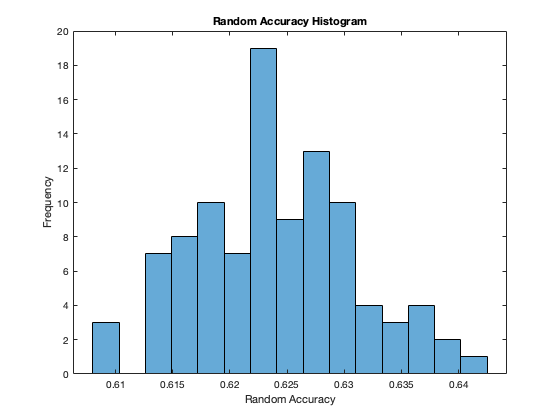

histogram(accuracy_guess,15);
xlabel("Random Accuracy")
ylabel("Frequency")
title("Random Accuracy Histogram")

Use t-test to compare the accuracy of random guess with actual accuracy.

[h_acc, p_acc] = ttest2(accuracy, accuracy_guess)

h_acc = 1

p_acc = 2.0303e-14

Repeat for precision and recall.

precision_guess = zeros(100,1);
recall_guess = zeros(100,1);
for i = 1:100
    random_pred = Ytrain(randperm(length(Ytest)));
    precision_guess(i,1) = sum(random_pred==1 & Ytest==1)/sum(random_pred);
    recall_guess(i,1) = sum(random_pred==1 & Ytest==1)/sum(Ytest);
end

mean(precision_guess)

ans = 0.2508

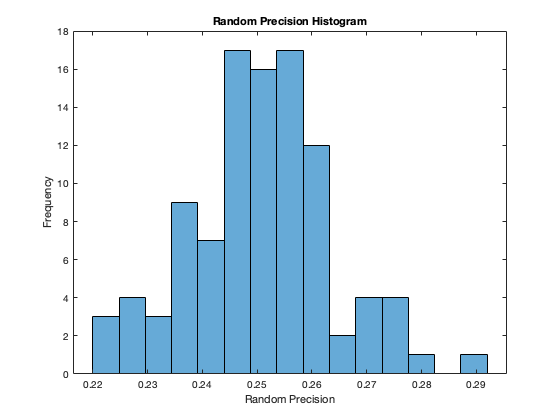

histogram(precision_guess,15);
xlabel("Random Precision")
ylabel("Frequency")
title("Random Precision Histogram")

mean(recall_guess)

ans = 0.2485

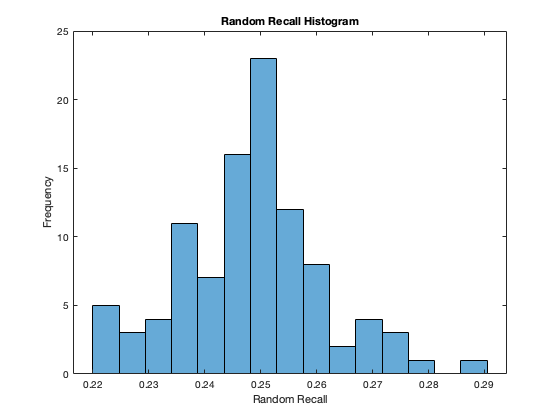

histogram(recall_guess,15);
xlabel("Random Recall")
ylabel("Frequency")
title("Random Recall Histogram")

[h_prec, p_prec] = ttest2(precision, precision_guess)

h_prec = 1

p_prec = 6.0459e-47

[h_recall, p_recall] = ttest2(recall, recall_guess)

h_recall = 1

p_recall = 3.2331e-60